% Define the system
s = tf('s');
sys = (1.3*(s+12))/((s+3)*(s+5)*(s+2));

% Find Ku and Pu (You need to do this experimentally or through simulation)
% For demonstration, let's assume Ku and Pu are given
Ku = 103; % Replace with your calculated value
Pu = 0.49; % Replace with your calculated value

% Calculate PID parameters using Ziegler-Nichols closed-loop method
Kp = 0.6 * Ku;
Ti = 0.5 * Pu;
Td = 0.125 * Pu;
Ki = Kp / Ti;
Kd = Kp * Td;

% Create the PID controller 
cont = pid((Kp),(Ki),(Kd*4.5));

disp(Kp)

   61.8000



disp(Ki)

  252.2449



disp(Kd)

    3.7852



time =          0    0.0025    0.0050    0.0075    0.0100    0.0125    0.0150    0.0175    0.0200    0.0225    0.0250    0.0275    0.0300    0.0325    0.0350    0.0375    0.0400    0.0425    0.0450    0.0475    0.0500    0.0525    0.0550    0.0575    0.0600    0.0625    0.0650    0.0675    0.0700    0.0725    0.0750    0.0775    0.0800    0.0825    0.0850    0.0875    0.0900    0.0925    0.0950    0.0975    0.1000    0.1025    0.1050    0.1075    0.1100    0.1125    0.1150    0.1175    0.1200    0.1225


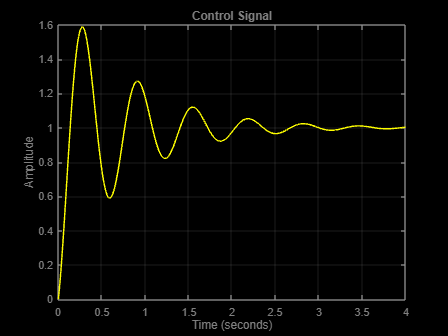


% Closed-loop system
closedLoopSys = feedback(cont*sys, 1);

% Time vector
time = 0:0.0025:6; % Adjust time vector as needed

% Step response of the closed-loop system
[response, time] = step(closedLoopSys, time);

% Compute the error signal (assuming a unit step input)
ref_input = ones(size(time)); % Reference input (step)
error_signal = ref_input - response; % Error signal

% Compute the PID components manually
P = Kp * error_signal;
I = Ki * cumtrapz(time, error_signal);  % Integral component
D = Kd * [0; diff(error_signal)./diff(time)];  % Derivative component

% Compute the control signal
control_signal = P + I + D;

% Plotting the control signal
figure;
plot(time, control_signal, 'y'); % Plot with yellow line
set(gcf, 'Color', 'k'); % Set figure background to black
set(gca, 'Color', 'k', 'XColor', [0.5 0.5 0.5], 'YColor', [0.5 0.5 0.5], 'GridColor', [0.5 0.5 0.5]); % Set axes colors
grid on; % Enable grid
title('', 'Color', [0.5 0.5 0.5]);
xlabel('Time (seconds)', 'Color', [0.5 0.5 0.5]);
ylabel('', 'Color', [0.5 0.5 0.5]);
